# Understanding the melodymatching function

© Noelia Martínez-Molina, 15-03-2022

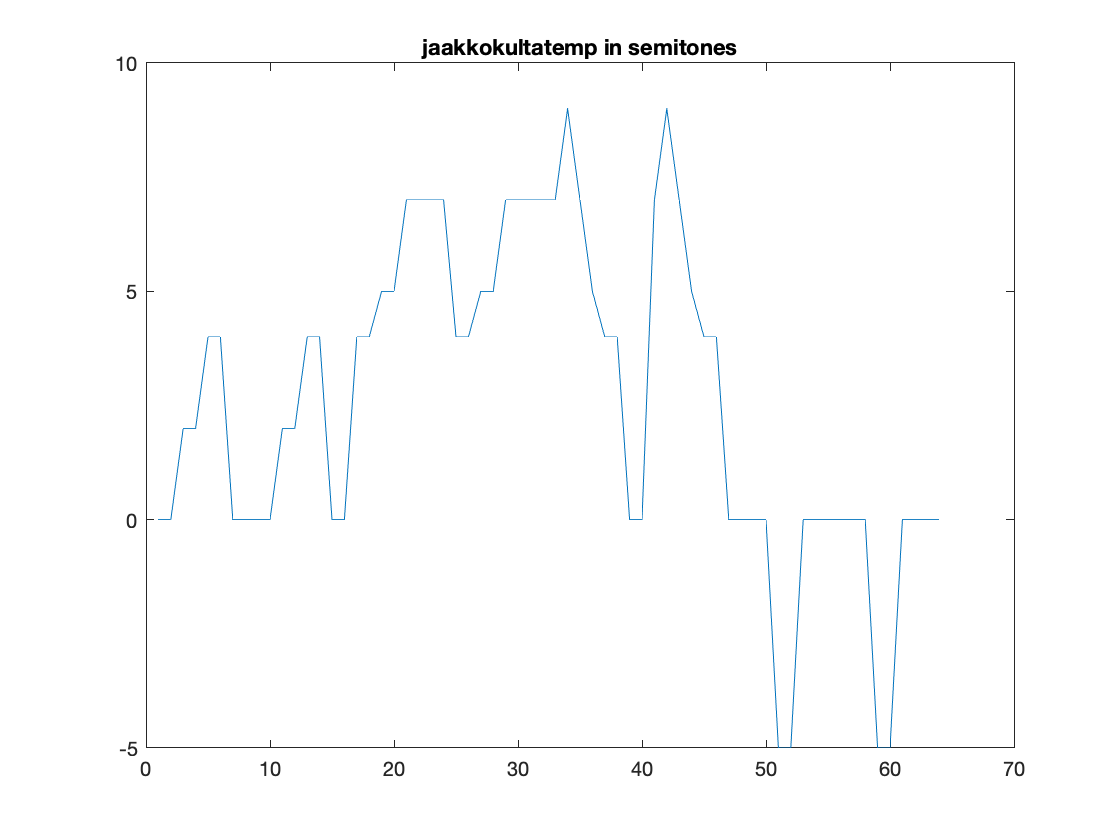

clear all, close all
% Specify paths, template and fname
data_path='/Volumes/LASA/Aphasia_project/Acoustic_analysis/singing_stimuli/FJ_Model/data/';
code_path='/Users/noeliamartinezmolina/Documents/GitHub/jaakkokulta_currentcode/';
output_path='/Volumes/LASA/Aphasia_project/Acoustic_analysis/singing_stimuli/FJ_Model/results/';
addpath(code_path)
addpath(fullfile(code_path,'yin'))
fileExtension = '.mp3';
temp=[0 0 2 2 4 4 0 0 0 0 2 2 4 4 0 0 4 4 5 5 7 7 7 7 4 4 5 5 7 7 7 7 7 9 7 5 4 4 0 0 7 9 7 5 4 4 0 0 0 0 -5 -5 0 0 0 0 0 0 -5 -5 0 0 0 0]; %
figure, plot(temp),title ('jaakkokultatemp in semitones')

% NOELIA Q1: How were these values obtained? It looks like there's a pair of identical values for each syllable in Jaakko kulta (Nsyl=32, length
%jaakkojultatemp=64)

The template values are expressed in number of semitones with respect to the tonic (I haven't tested it, but I think you would get identical results if you summed or subtracted any value to the template). The sample points correspond to eighth notes; the resolution of the template is based on the fastest pitch jumps that we have in this tune (i.e., the '7 9 7 5' part, which corresponds to the 'Kellojasi soita' part). So the template is a 'ja-a-kko-o-ku-ul-ta-a' kind of melody. This means that the algorithm is not sensitive to whether you sing 'ja-a-kko' or 'jaa-kko'. Also, it doesn't know in which parts there should be a silence in the tune.

cd (data_path)
d = dir('*_48k_1rep.mp3');
fname = d(1).name;
 
% Specify input parameters for the yin f(x)
par.thres = 0.1; % amplitude threshold for trimming
par.minf0 = 30; % Hz - minimum expected F0 (default: SR/(4*dsratio))
par.maxf0 = 1000; % Hz - maximum expected F0
par.hop = 32; % samples - interval between estimates (default: 32). NOELIA: Set this back to default. 
yinpar.minf0 = par.minf0;
yinpar.maxf0 = par.maxf0;
yinpar.hop = par.hop;
thres=par.thres;

N=length(temp);


## 1. Estimate pitch and amplitude with yin

 yinout is a STRUCT with 4 fields of interest (1x25796 arrays (max. range/hop)) including:

- f0: fundamental frequency in octaves re: 440 Hz

- ap0 & ap: aperiodicity measure (ratio of aperiodic to total power)

- pwr: period-smoothed instantaneous power 

%NOELIA C1: sr=44100 currently and should be changed to 48kHz to match the recording's
% value
yinout=yin(fname,yinpar);

guessing format of JK_female_singing_cut_mono_48k_1rep.mp3...


i = struct with fields:
     fname: 'JK_female_singing_cut_mono_48k_1rep.mp3'
        fd: 3
    nbytes: 222321
    format: 'MP3'


MP3


f0=yinout.f0; 
pitch0=69+12*f0; % NOELIA Q2: what is this conversion doing? pitch0 range(1.17,-3.87)
pitch=medfilt1(pitch0,3); % slight median filtering for noise cleaning

Here the yin output (expressed as fundamental frequency in octaves with respect to 440Hz) is converted to frequency data values. After this conversion, the pitch estimates are expressed in number of semitones with respect to middle C. Now the extracted pitch has been scaled to resemble the template (but still needs to be transposed, which will be done in step 5 of the code).

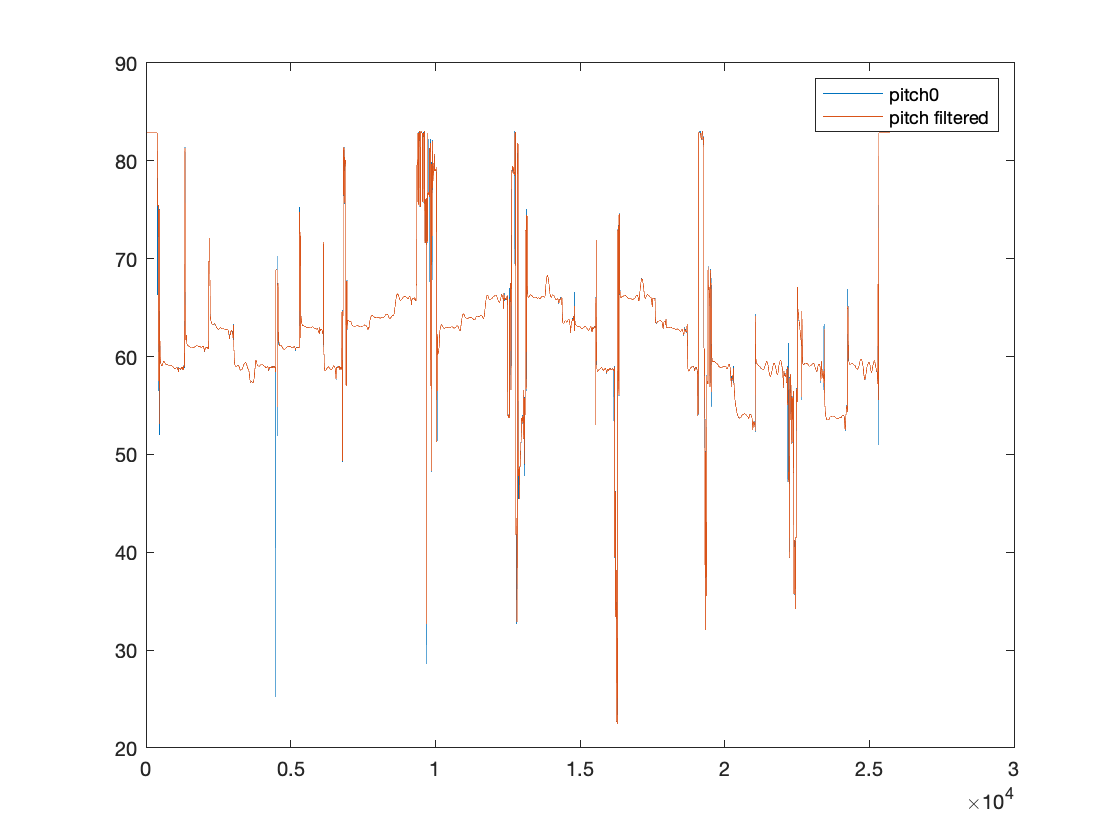

amp=sqrt(yinout.pwr);
amp=amp/max(amp); % normalize max amplitude
M=length(pitch);

figure, plot(pitch0),hold on, plot(pitch), legend('pitch0','pitch filtered')

## 2. Trim audio based on amplitude thresholding

ind=find(amp>thres);
start=min(ind);
stop=max(ind);
pitch1=pitch(start:stop);
amp1=amp(start:stop);
incl1=find(amp1>thres*nanmedian(amp1));
M1=length(pitch1);


## 3. Interpolate template to match pitch curve length

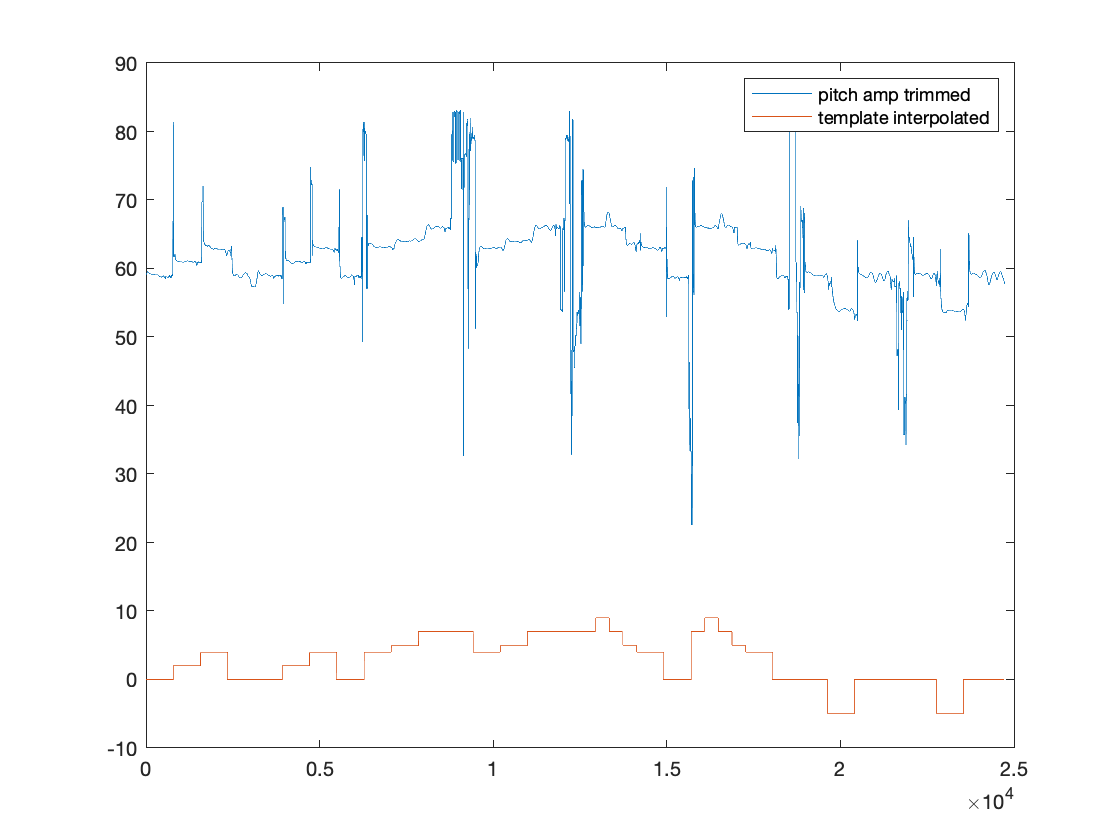

temp1=interp1(linspace(0,1,N),temp,linspace(0,1,M1),'previous');

figure
plot(pitch1), hold on, plot(temp1), legend('pitch amp trimmed','template interpolated')

## 4. Remove timepoints below threshold amplitude

pitch2=pitch1(incl1);
temp2a=temp1(incl1);
amp2=amp1(incl1);


## 5. Match pitch and template means

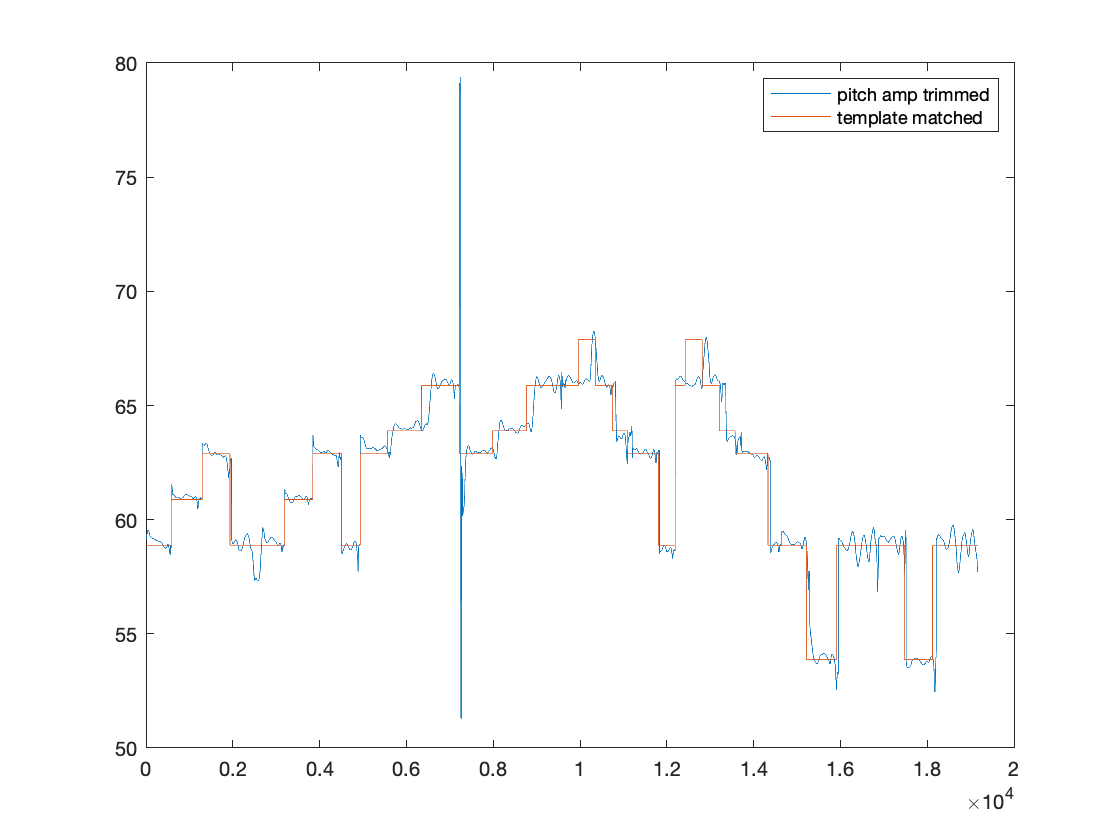

temp2=temp2a+mean(pitch2)-mean(temp2a);

figure,plot(pitch2), hold on, plot(temp2) ,legend('pitch amp trimmed','template matched')

## 6. Dynamic Time Warping

`[`[`dist`](https://www.mathworks.com/help/releases/R2021a/signal/ref/dtw.html?doclanguage=en&nocookie=true&prodfilter=ML%20BI%20CF%20NN%20IA%20IP%20MG%20ME%20CO%20MJ%20MR%20DM%20SG%20ST&docviewer=helpbrowser&docrelease=R2021a&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3D0PPTDA&searchsource=mw&snc=AVUG4K&container=jshelpbrowser#bu1ymix-dist)`,`[`ix`](https://www.mathworks.com/help/releases/R2021a/signal/ref/dtw.html?doclanguage=en&nocookie=true&prodfilter=ML%20BI%20CF%20NN%20IA%20IP%20MG%20ME%20CO%20MJ%20MR%20DM%20SG%20ST&docviewer=helpbrowser&docrelease=R2021a&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3D0PPTDA&searchsource=mw&snc=AVUG4K&container=jshelpbrowser#bu1ymix-ix)`,`[`iy`](https://www.mathworks.com/help/releases/R2021a/signal/ref/dtw.html?doclanguage=en&nocookie=true&prodfilter=ML%20BI%20CF%20NN%20IA%20IP%20MG%20ME%20CO%20MJ%20MR%20DM%20SG%20ST&docviewer=helpbrowser&docrelease=R2021a&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3D0PPTDA&searchsource=mw&snc=AVUG4K&container=jshelpbrowser#bu1ymix-iy)`] = dtw(`[`x`](https://www.mathworks.com/help/releases/R2021a/signal/ref/dtw.html?doclanguage=en&nocookie=true&prodfilter=ML%20BI%20CF%20NN%20IA%20IP%20MG%20ME%20CO%20MJ%20MR%20DM%20SG%20ST&docviewer=helpbrowser&docrelease=R2021a&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3D0PPTDA&searchsource=mw&snc=AVUG4K&container=jshelpbrowser#bu1ymix-x)`,`[`y`](https://www.mathworks.com/help/releases/R2021a/signal/ref/dtw.html?doclanguage=en&nocookie=true&prodfilter=ML%20BI%20CF%20NN%20IA%20IP%20MG%20ME%20CO%20MJ%20MR%20DM%20SG%20ST&docviewer=helpbrowser&docrelease=R2021a&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3D0PPTDA&searchsource=mw&snc=AVUG4K&container=jshelpbrowser#bu1ymix-y)`)` returns the common set of instants, or *warping path*, such that `x`(`ix`) and `y`(`iy`) have the smallest possible `dist` between them.

The vectors `ix` and `iy` have the same length. Each contains a monotonically increasing sequence in which the indices to the elements of the corresponding signal, `x` or `y`, are repeated the necessary number of times.

Output arguments:

- d: Minimum distance between signals, returned as a positive real scalar. 

- idx: Warping path for first signal, returned as a vector or matrix of indices.

- idy: Warping path for second signal, returned as a vector or matrix of indices.

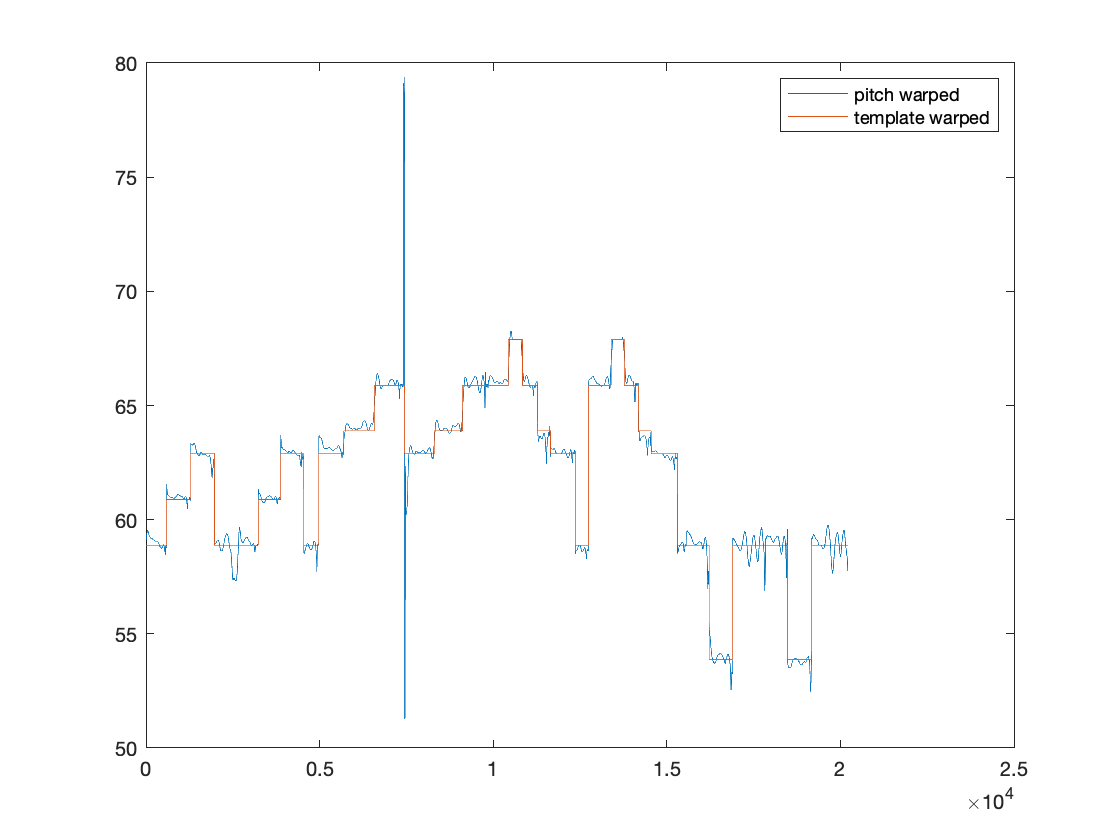

metrics={'absolute','euclidean','squared','symmkl'};
m=2;
[d,idx,idy]=dtw(pitch2,temp2,metrics{m}); %euclidean
pitch3=pitch2(idx);
amp3=amp2(idx);
temp3=temp2(idy);

figure,plot(pitch3), hold on, plot(temp3) ,legend('pitch warped','template warped')

## 7. Remove pitch outliers

incl3=find(abs(pitch3-temp3)<2.5*std(pitch3-temp3));
pitch4=pitch3(incl3);
temp4a=temp3(incl3);
amp4=amp3(incl3);
M4=length(pitch4);

## 8. Match pitch and template means

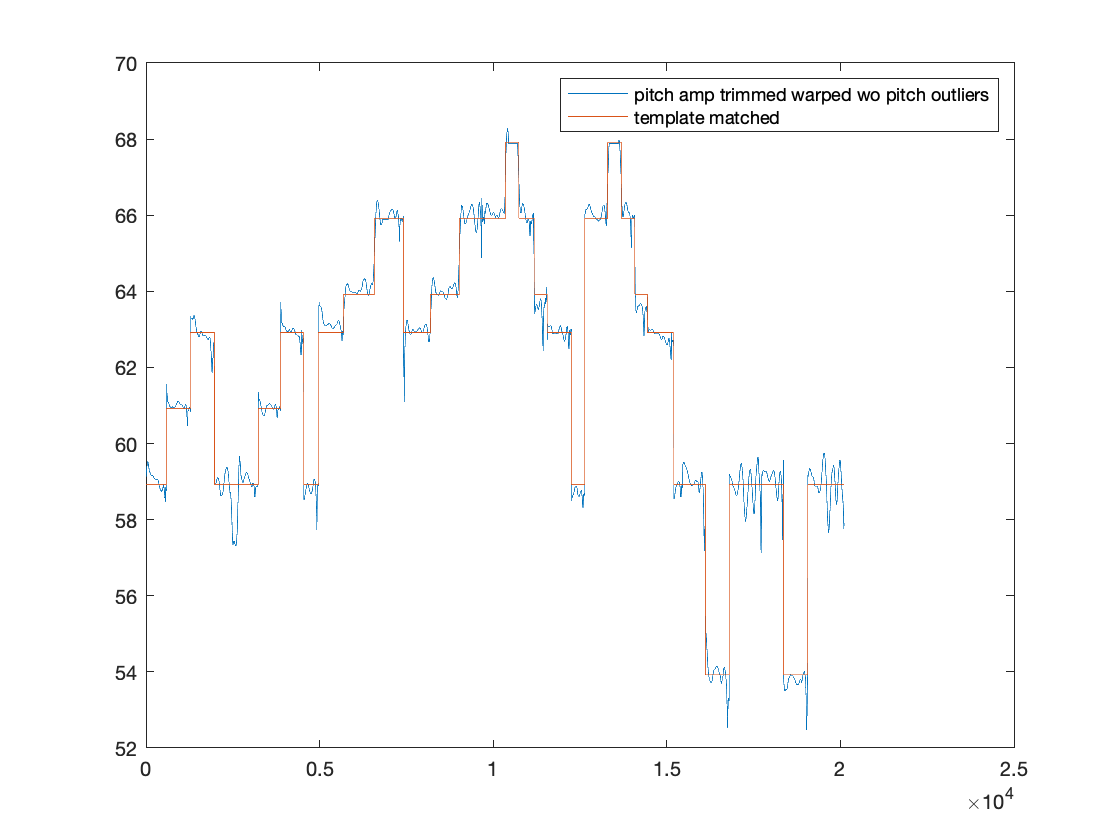

temp4=temp4a+mean(pitch4)-mean(temp4a);

figure,plot(pitch4), hold on, plot(temp4) ,legend('pitch amp trimmed warped wo pitch outliers','template matched')

## 9. Rhythm error score

out.rhythmerror=(sum(diff(idx)==0)+sum(diff(idy==0)))/length(idx); %NOELIA Q3: don't understand why the rythm error was calculated from the warping path. What does it mean that there's no difference between adjacent idx elements? 

If consecutive index elements are identical, this means that the signals have been temporally aligned by the time warping algorithm. That is, there is a temporal misalignment between pitch jumps in the pitch curve and those in the template. But it could totally mean that the singer was being more expressive.

## 10. Pitch error score 1: no segmenting, no trend removal amplitude-weighted mean absolute error

pe4=pitch4-temp4;
out.pitcherror(1)=sum(amp4.*abs(pe4))/sum(amp4); % amplitude weighted mean abs error, why is this weighted by the mean?


## 11. Pitch error score 2: no segmenting, trend removal

pe4d=detrend(pe4);
out.pitcherror(2)=sum(amp4.*abs(pe4d))/sum(amp4); % amplitude weighted mean abs error


## 12. Segment pitch data based on template pitch changes

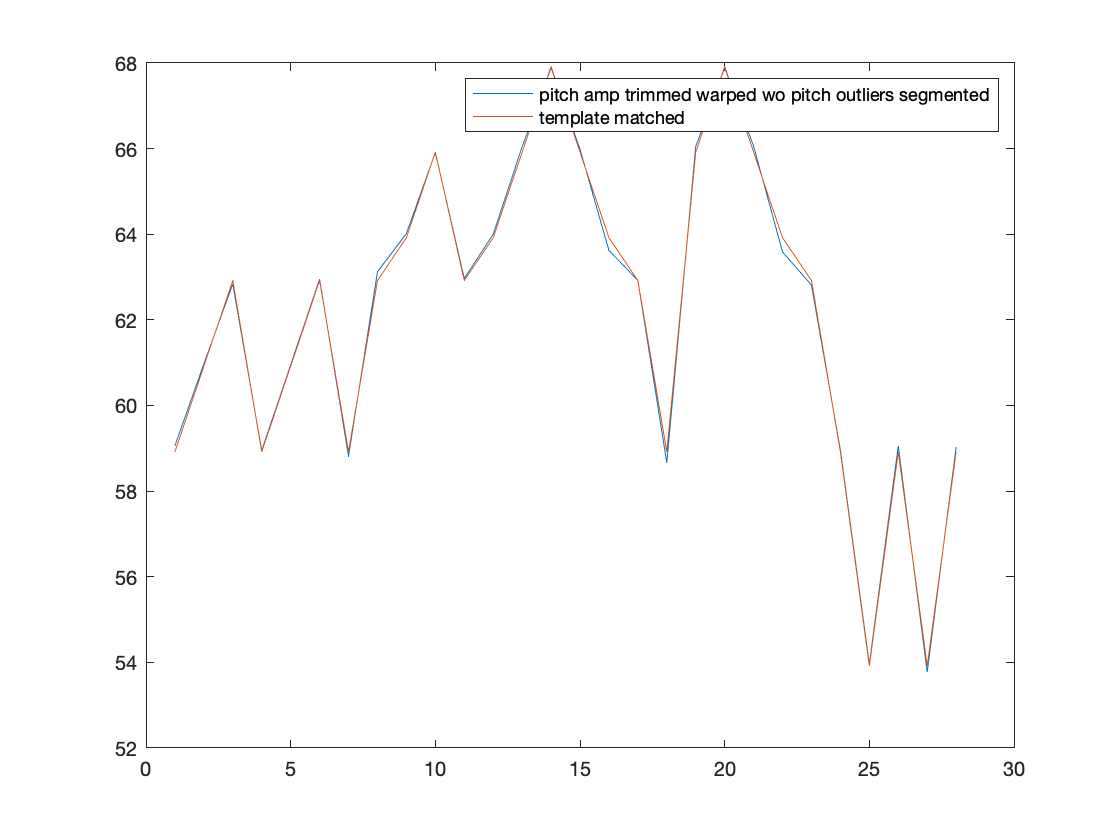

stop=[find(abs(diff(temp4))>0) length(temp4)]; % end of each segment
start=[1 stop(1:end-1)+1]; % beginning of each segment
for k=1:length(start)
    pitch5(k)=median(pitch4(start(k):stop(k))); % NOELIA Q4: why is the median taken in this case?
    temp5(k)=temp4(start(k));
end

figure,plot(pitch5), hold on, plot(temp5) ,legend('pitch amp trimmed warped wo pitch outliers segmented','template matched')

I think that this is because the goal here is to get the most frequent pitch value in the segment. Taking the mean would be problematic due to sensitivity to outliers in the pitch curve. Taking the mode is also an option in my opinion (if the distribution happens to be bimodal, the median will not be representative anyway). In other parts of the code, mean is either used to center the signals or to compute a (weighted) average across segments or across the whole song.

## 13. Pitch error score 3: segmenting, no trend removal

pe5=pitch5-temp5;
out.pitcherror(3)=mean(abs(pe5));


## 14. Pitch error score 4: segmenting, trend removal

pe5d=detrend(pe5);
out.pitcherror(4)=mean(abs(pe5d));


## 15. Pitch error score 5: parsons code distance

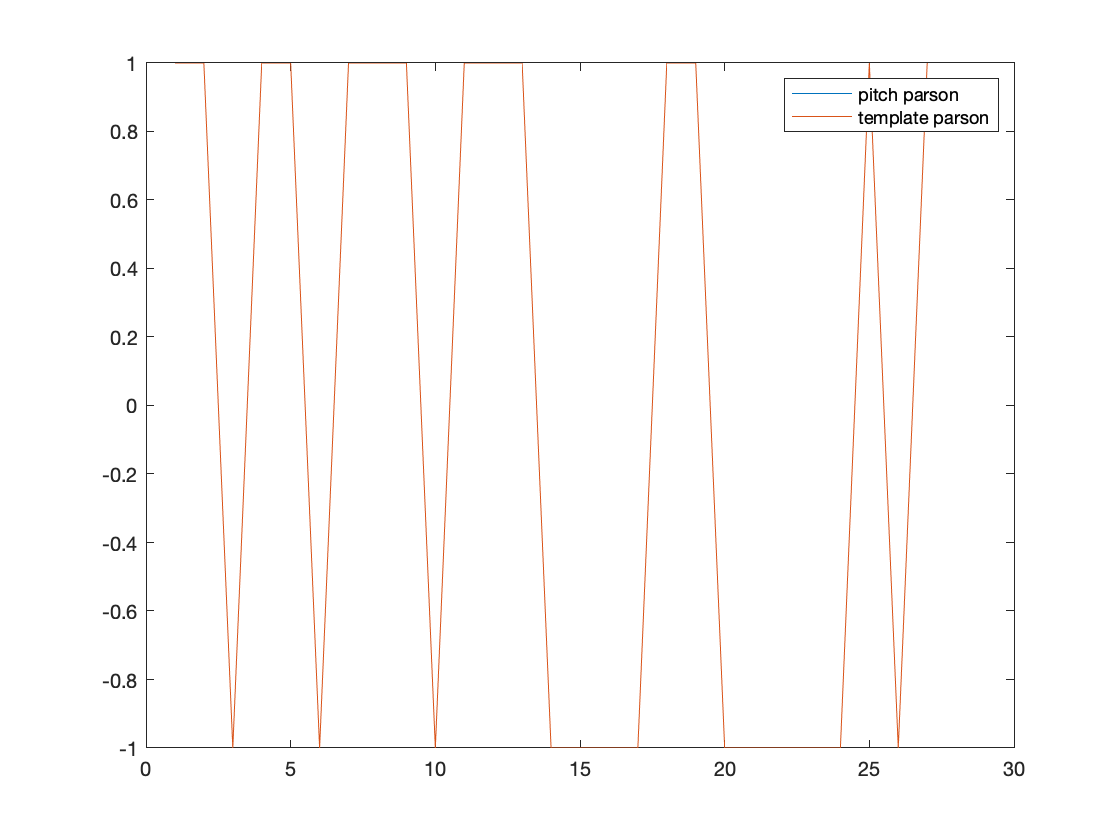

pitch6=sign(diff(pitch5));
temp6=sign(diff(temp5));
out.pitcherror(5)=sum(abs(pitch6-temp6));

figure,plot(pitch6), hold on, plot(temp6) ,legend('pitch parson','template parson')


out.pitch = {pitch pitch1 pitch2 pitch3 pitch4 pitch5 pitch6};
out.temp = {temp temp1 temp2 temp3 temp4 temp5 temp6};
out.amp={amp amp1 amp2 amp3 amp4};